format short
u = symunit;
% separateUnits(x)
% separateUnits(x_si)

# BOLTE OG SPINDLER

## Alle formler omhandler Metriske ISO gevind - M og MJ(fly ISO 5855)

For en **M10 x 1,5** bolt gælder


$$d=10mm$$



$$p = 1,5mm$$


Hvis der stå **8.8 **på en bolt så er

første tal Brudstyrken * 100 MPa her = 800 MPa

andet tal flydespændingen som antal procent * 10% af brudstyrken her = 800 MPa * 0.8

for proof strength se **Table 8-11**

#### Variable

Tabeller og billeder er fra shigleys eller bolt noter

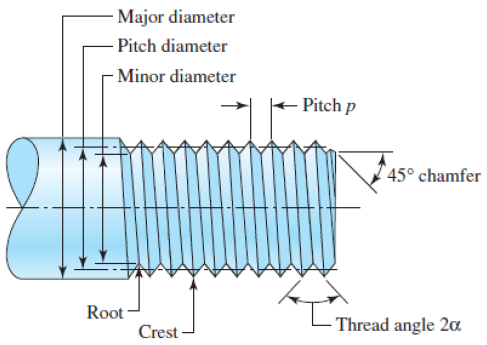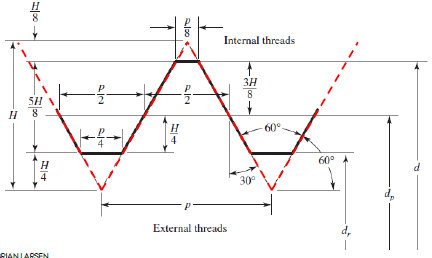

- $d$ - Skaft diameter eller spindeldiameter (major diameter eller nominelle diameter) [mm]

- $d_r$ - Rod diameter (minor diameter) [mm]

- $d_p$ - Pitch diameter [mm]

- $d_m$ - middeldiameter - kvadratisk gevind(højde og brede af gevind er ens) [mm]

- $d_t$ -  Træk diameteren [mm]

- $d_c$ - Krave diameteren (for krave betydning **se figur 8-7**)) [mm]

- $H$ - Højde af genvind hvis det var trekantet [mm]

- $p$ -  Pitch eller Stigning på gevind (afstand top til top) [mm]

- $n$ - Antal gevind 

- $l$ - Lead(flytning) [mm] pr omdrejning

- $G_d$ - gevinddybde [mm]

- $G_w$ - gevindbrede [mm]

- $A_t$ - Trækspændingsareal (Se **tabel 8-1**) OBS kan også findes med $d_t$ [mm^2]

- $A_d$ - Skaftareal [mm^2]

- $\lambda$ - stigningsvinkel (i dette script angives det i grader)

- $f$ - Friktionskoefficient for gevind

- $f_c$ - Friktionskoefficient for krave (stykke der holde pladen fra gevindet, **se figur 8-7**)

- $v$ - lineær hastighed [mm/s]

- $\omega$ - omdrejningshastighed [1/s]

## Generelt

d =  10;                % Skaft diameter (major diameter)
d_r = 9;                % Rod diameter (minor diameter)
d_p = (d + d_r)/2;      %Pitch diameter
d_t = (d_r + d_p)/2;    % Træk diameteren

lamda = 30

p = 1.5;                % Pitch (afstand top til top)
H = sqrt(3)/2 * p;      % Højde af genvind
A_t = pi/4 * d_t^2;     % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t
lamda = 30 %stigningsvinkel i grader til dette script

## SPINDEL GEOMETRI FOR KVADRATISK GEVIND

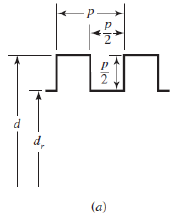

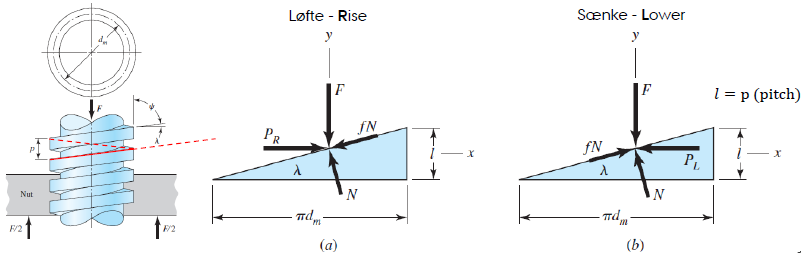

% SPINDEL GEOMETRI FOR KVADRATISK GEVIND
n = 1;                  % antal gevind
l = p * n;              % Lead(flytning) 
G_d = p/2;              % gevinddybde
G_w = p/2;              % gevindbrede
d_r = d - p;            % rod diameter - kvadratisk
d_m = d - p/2;          % middeldiameter
v = 1;                  % lineær hastighed
omega = v/l * 2*pi      % omdrejningshastighed

% Hæve en last(løfte - rise)
%kraften
P_R = (F * (sind(lambda) + f * cosd(lambda))) /...
    (cosd(lambda) - f * sind(lamda))

% tan(lambda) = l / (pi * d_m) % til at omskrive til moment

% moment
T_R = F * d_m / 2 * ((l + pi * f * d_m) / ...
    (pi * d_m - f * l)) %ligning 8-1


% Hæve en sænke(lower)
%kraften
P_R = (F * (f * cosd(lambda) - sind(lambda))) /...
    (cosd(lambda) + f * sind(lamda))

% tan(lambda) = l / (pi * d_m) % til at omskrive til moment

%moment
T_R = F * d_m / 2 * ((pi * f * d_m - l) / ...
    (pi * d_m + f * l)) % ligning 8-1

%spindel med krave moment (se figur 8-7 for krave betydning)
T_c = F * f_c * d_c / 2 % ligning 8-6


%selv låsende gevind
% Hvis det moment, der skal påføres for at sænke lasten, er positivt, siges gevindet at være
% selvlåsende. Så ligning 8-2 skal resultere i:

% tan(lambda) = l / (pi * d_m)

test = l / (pi * d_m) % eller tan(lambda) %alt efter hvad der er til rådighed

if f > test
    disp("Gevindet er selvlåsende!")
else
    disp("Gevindet er IKKE selvlåsende")
end



%virkningsgrad
T_R = F * d_m / 2 * ((l + pi * f * d_m) / ...
    (pi * d_m - f * l)) %Power ind med friktion  %ligning 8-1

T_O = F*l/(2*pi) %Power ud uden friktion %ligning g

% Virkningsgrad
e = T_O / T_R % = F*l/(2*pi*T_R) % ligning 8-4

# FORSPÆNDTE BOLTESAMLINGER

#### Variable

Tabeller og billeder er fra shigleys eller bolt noter

- $d$ - Nominel diameter (skaft)  [mm]

- $l$ - Klemme længde (regnes kun til midt i underlagets nedre del, se **figur 8-14**) [mm]

- $L$ - Boltlængde  [mm]

- $L_t$ - Gevindlængde  [mm]

- $l_d$ - Skaft længde  [mm]

- $l_t$ - Gevindlængde i indgreb  [mm]

- $H$ - Højde på møtrik (se også **table A-29**) [mm]

- $W$ -  Nøglevidde eller washer face (spændeskive overflade se **table A-29 **og **Figur 8-9**) [mm]

- $t$ - Tykkelse på spændeskiven [mm]

- $R$ - Rundingsradius (se også **table A-29**) [mm]

- $A_t$ - Trækspændingsareal [mm^2]

- $A_d$ - Skaftareal [mm^2]

- $k_b$ - Boltens stivhed [N/mm]

- $k_m$ - Underlagets stivhed [N/mm] - se også side 20 og frem i bolte 2 slides

- $k_d$ - Stivhed på boltstykket uden gevind 

- $k_t$ - Stivhed af gevindstykket

- $C$ - Samlingens stivhedskonstant

- $E$ - E-modul 

- $\alpha$ - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2

## Bolte & Møtrikker

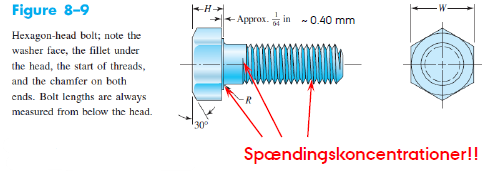

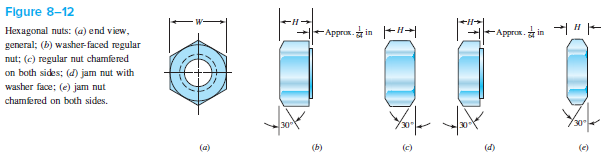

d = 10;             % Nominel diameter (skaft)  [mm]
l =  100;           %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]
L = 150;            % Boltlængde  [mm]
L_T = 130;          % Gevindlængde  [mm]
l_d = 30;           % Skaft længde  [mm]
l_t = 70;           % Gevindlængde i indgreb  [mm]
H = 20;             % Højde på møtrik (se også table A-29) [mm]
W = 40;             % Nøglevidde eller washer face se table A-29 [mm]
t = 2;              % 
R = 2;              % Rundingsradius (se også table A-29)[mm]
A_t = pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t
A_d = pi/4 * d^2;   % Skaftareal [mm^2]
k_b = 100;          % Boltens stivhed [N/mm]
k_m = 100;          % Underlagets stivhed [N/mm]
C = 2;              % Samlingens stivhedskonstant

%længde af gevind(L_T) følger normalt (8-14)

if L <= 125 && d <= 48
    L_T = 2*d + 6
elseif 125 < L && L<= 200
    L_T = 2 * d + 12
elseif L > 200
    L_T = 2 * d + 25
else
    disp("Hmmm something is wrong")
end


%BOLTENS STIVHED
%For stykket uden gevind
k_d = (A_d * E) / l_d %ligning 8-16

%kan udledes fra
% sigma = F/A
% F = k * delta
% sigma = E * epsilon
% epsilon = Delta L / L = delta / L

% For gevindstykket gælder
k_t = A_t * E / l_t % ligning 8-16

%samlede stivhed når to elementer klemme sammen
k_b = (A_d * A_t * E) / (A_d * l_t + A_t * l_d)

## YDRE BELASTNING AF FORSPÆNDT SAMLING

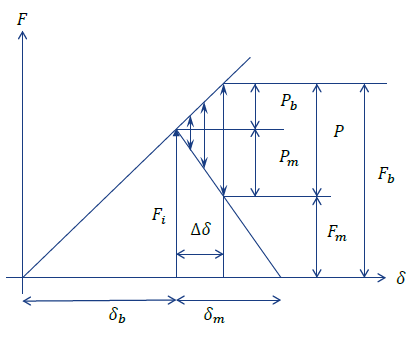

- $F_i$ - forspændingskraft på bolt

- $S_p$ - er proof strength (**table 8-11**) hvis de ikke findes i tabellen $S_p = 0,85 * S_y$

- $\delta_b$ - forlængelse af bolt

- $\delta_m$ - sammentrykning af underlag

- $P$ - ydre last []

- $P_b$ - andel af ydre last der går i bolten

- $P_m$ - andel af ydre last der går i underlaget

- $F_m$ - klemmekraft i underlaget

- $F_b$ - samlet kraft i bolten

- $\Delta \delta$ - forlængelse af bolt fra ydre last

- $\Delta \delta$ - sammenklemning af underlag fra ydre last

Delta_delta = P_b / k_b %forlængelse af bolt
Delta_delta = P_m / k_m %forlængelse af matriale


%Samling stivhedskontanten
C = k_b / (k_b + k_m)


% Spændinger i bolten kan beregnes som
sigma_b = F_b/A_t

P_b = C * P
sigma_b = (F_i + P_b) / A_t


% Sikkerhed imod flydning

n_p = S_p / sigma_b % ligning 8-28


%seperation så længe forspændingskraften er større end den andel af den ydre last der går i underlaget
% P_m > F_i

P_b = C * P

P_m = P(1 - C)

% P = P_b + P_m

n_0 = F_i / P_m %sikkerhed


% LOAD FAKTOR
n_L = (S_p * A_t - F_i) / (C*P)



% ANBEFALET FORSPÆNDING
F_p = A_t * S_p

F_i = 0.75 * F_p % for IKKE permenente bolte ligning (8-31)
F_i = 0.90 * F_p % for permenente bolte ligning (8-31)






## Nyttige figurer til bolte og møtrikker

**Skruesamling**

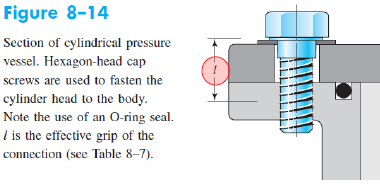

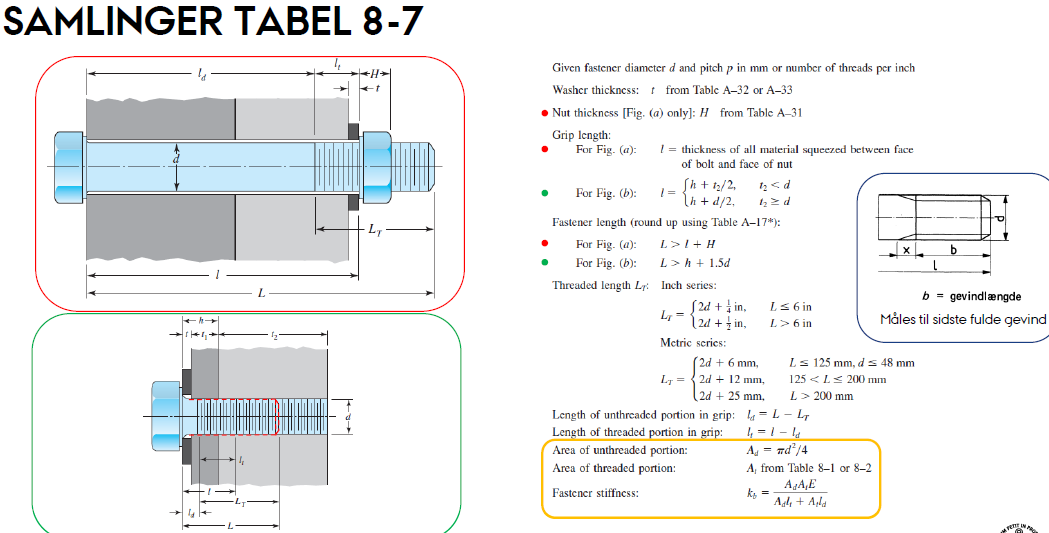

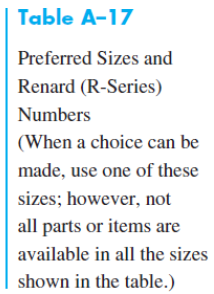

Tabel A-17 anviser hvilke tilgængelige længder der kan anvendes hvis man får en "Skæv længde"

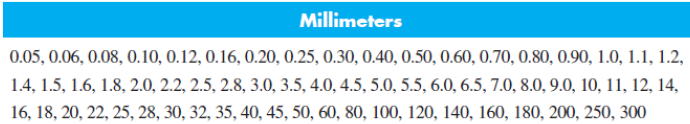

En ideel boltelængde har et par gevind rynker synlig uden for møtrikken!

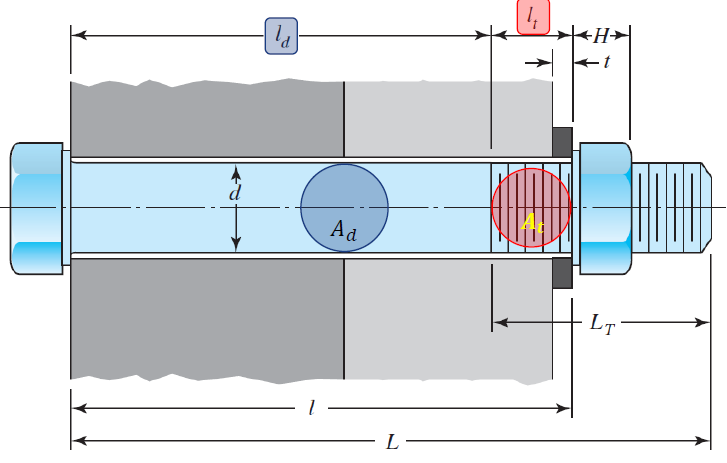

Tryk reglen, vinklen er $\alpha$ -- se også Formel (8-19) som er udledt i kapitel 8-5 eller side 20 i bolte 2

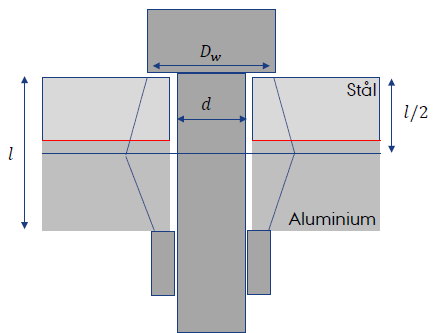

# Brugbare tabeller

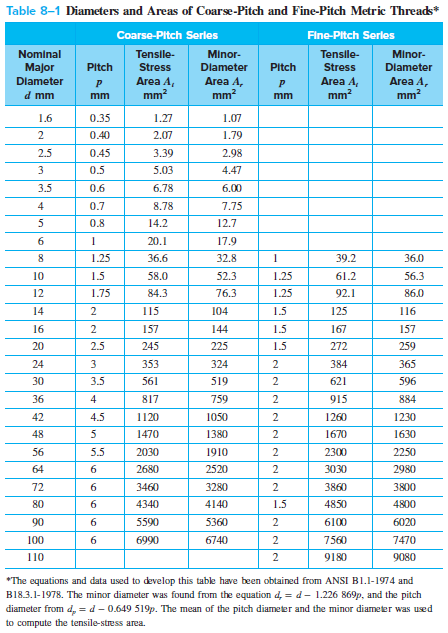

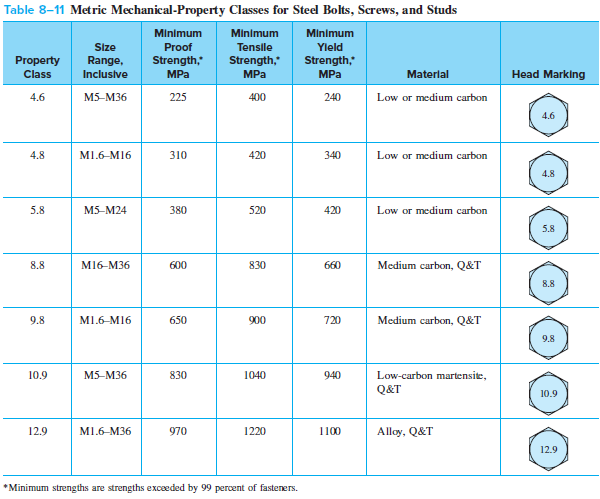

ved 8.8 er der fejl ved size range den går længere ned end M16

Friktionstabeller for $f$ og $f_c$